# **9-1 Model fitting to data using LSM** 

## **PART I: Fitting the catalytic model to seroprevalence data to estimate the force of infection**

We will first analyze the data from the UK (“seroprevalence_uk”):

Ignoring the maternal antibodies, write the formula for the proportion of age “a” who have ever been infected in terms of force of infection “                              ”.

clc;clear;close all
% Data불러오기
T_uk = readmatrix("seroprevalence_uk.csv");
age_uk = T_uk(:,1);
p_sero_uk = T_uk(:,2)./T_uk(:,3);
T_ch = readmatrix("seroprevalence_china.csv");
age_ch = T_ch(:,1);
p_sero_ch = T_ch(:,2)./T_ch(:,3);

#### 1.Assume the initial value for the force infection in the UK to be 0.12. Do you think the true value for the force infection in the UK was greater or smaller than that currently assumed? What is the current value for squared error?

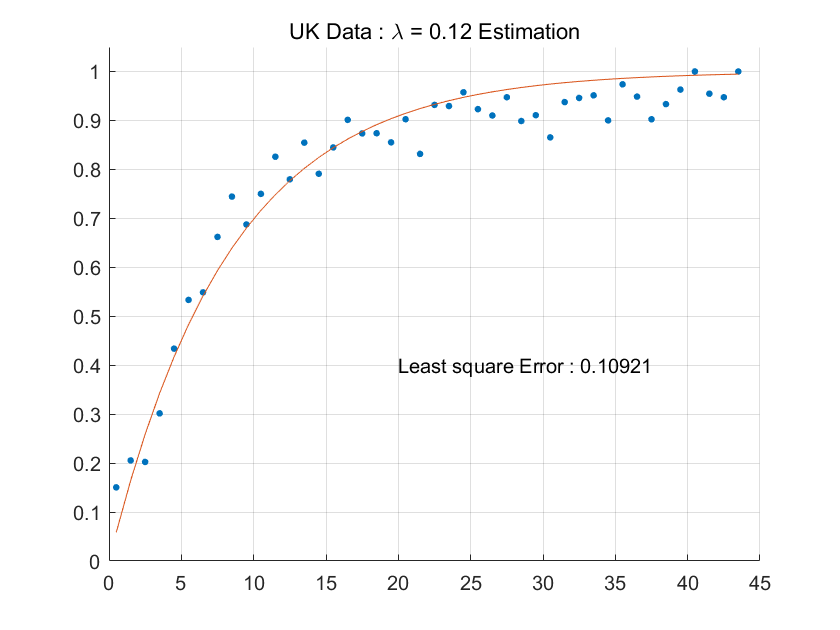

est_temp = 1-exp(-0.12*age_uk);
Error_temp = sum((est_temp-p_sero_uk).^2);

figure(1)
hold on
plot(age_uk,p_sero_uk,'.','MarkerSize',10)
plot(age_uk,est_temp,'-')
ylim([0,1.05])
title('UK Data : \lambda = 0.12 Estimation')
text(20,0.4,['Least square Error : ',num2str(Error_temp)])
grid on;
hold off

#### 2. What is the best-fitting value for the force of infection and the current value for squared error? Plot a graph of model predictions and observation.

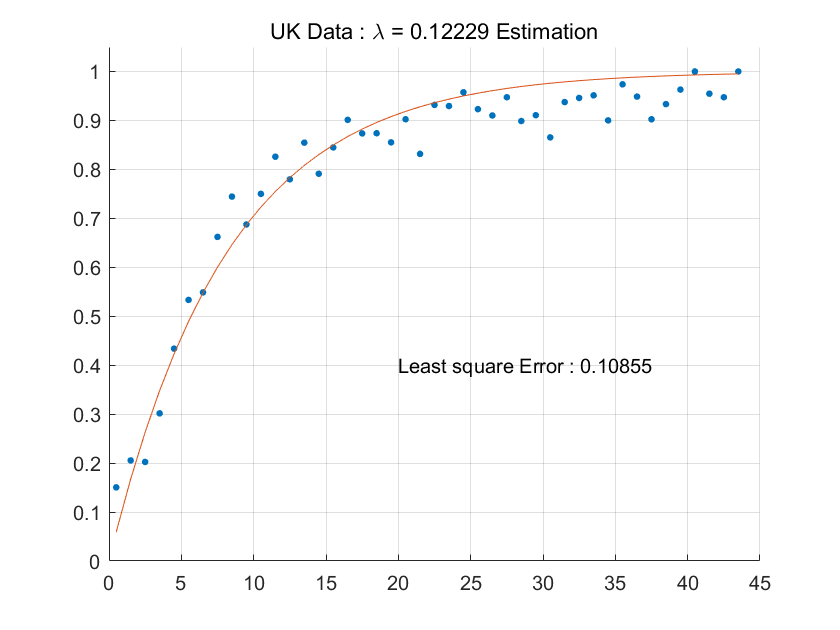

% best-fitting value for the force of infection
fun_uk = @(lambda) sum(2.*((1-exp(-lambda*age_uk))-p_sero_uk).*(exp(-lambda*age_uk)).*age_uk);
best_lam_uk = fzero(fun_uk,0.12);
est_uk = 1-exp(-best_lam_uk*age_uk);
Error_uk_m = sum((est_uk-p_sero_uk).^2);

figure(2)
hold on
plot(age_uk,p_sero_uk,'.','MarkerSize',10)
plot(age_uk,est_uk,'-')
ylim([0,1.05])
title(['UK Data : \lambda = ',num2str(best_lam_uk),' Estimation'])
text(20,0.4,['Least square Error : ',num2str(Error_uk_m)])
grid on;
hold off

#### 3. For which age groups does the model underestimate the proportion of individuals who are seropositive? For which age groups does it overestimate it?

대략 15세를 기점으로 15세 이하의 sero prevalance data는 undersetimate되었고 15세 이상의 sero prevalance data는 overestimate되었다.

#### 4. According to the formula, what is the average age at infection in the UK assuming that the force of infection is independent of age?

A_uk = 1/best_lam_uk;
fprintf('Average age is 1/lambda = %.2f years old',A_uk)

Average age is 1/lambda = 8.18 years old

#### 5. Assuming that the average life expectancy (L) is 60 years, what is the R0 for this population according to the expression R0=L/A? What is the herd immunity threshold?

R0_uk = 60/A_uk;
H_uk = 1-1/R0_uk;
fprintf('R0 is %.1f and Herd immunity threshold is %.2f%%',R0_uk,H_uk*100)

R0 is 7.3 and Herd immunity threshold is 86.37%

### **Fit the catalytic model to China data (“seroprevalence_china”) to estimate the force of infection:**

#### 6. Determine the best-fitting force of infection and plot a graph of model predictions and observed data. Calculate the average age at infection, the R0(assuming that the life expectancy is the same as that in the UK) and herd immunity. 

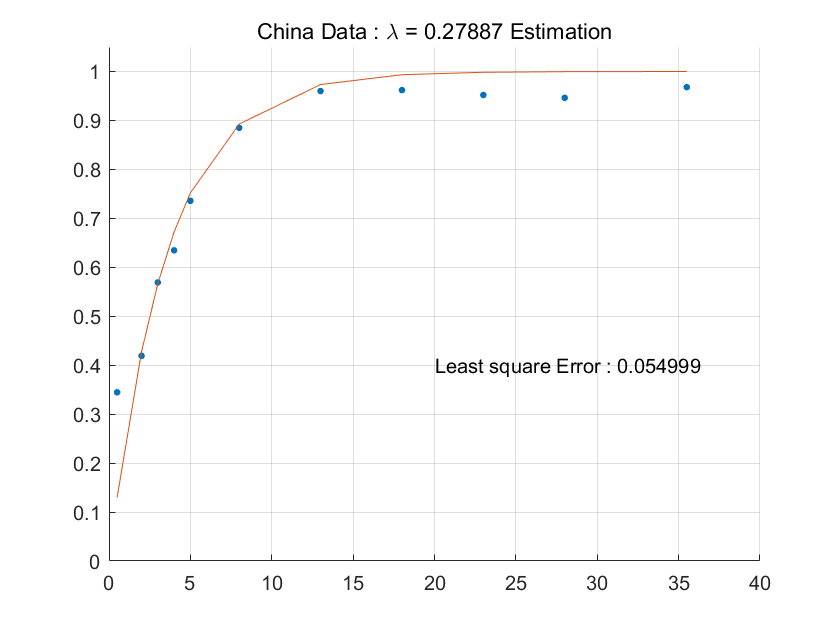

% best-fitting value for the force of infection
fun_ch = @(lambda) sum(2.*((1-exp(-lambda*age_ch))-p_sero_ch).*(exp(-lambda*age_ch)).*age_ch);
best_lam_ch = fzero(fun_ch,0.12);
est_ch = 1-exp(-best_lam_ch*age_ch);
Error_ch = sum((est_ch-p_sero_ch).^2);

figure(3)
hold on
plot(age_ch,p_sero_ch,'.','MarkerSize',10)
plot(age_ch,est_ch,'-')
ylim([0,1.05])
title(['China Data : \lambda = ',num2str(best_lam_ch),' Estimation'])
text(20,0.4,['Least square Error : ',num2str(Error_ch)])
grid on;
hold off

A_ch = 1/best_lam_ch;
R0_ch = 60/A_ch;
H_ch = 1-1/R0_ch;
fprintf(['Average age is 1/lambda = %.2f years old \n' ...
    'R0 is %.1f and Herd immunity threshold is %.2f%%'],A_ch,R0_ch,H_ch*100)

Average age is 1/lambda = 3.59 years old 
R0 is 16.7 and Herd immunity threshold is 94.02%

#### 7. How do the values for the force of infection, average age at infection, R0 and herd immunity threshold in China compare against those for the UK? Suggest possible reasons for these differences.

중국에서의 감염력이 훨씬 크게 나온것을 확인할 수 있다. 또한 R0값을 비교해도 중국이 16.7 (영국이 7.3)이므로 여러가지 이유로 중국의 감염력이 크다는 것을 설명할 수 있다. 

이러한 차이가 발생한 가장 큰 이유는 어린 연령층에서 항체비율이 중국이 훨씬 높은 data를 가지기 때문이다. 위생의 문제일 수도 있고 백신도입이 시작된 이후 수집된 data일 가능성도 있다. 

### Maternal Immunity

#### 8. Modify the expression for the prevalence of previous infection at each age assuming that individuals are immune for the first 6 months of life **as a result of maternal antibodies.**

#### 9. Assuming that individuals are immune for the first 6 months of life and are then susceptible, refit the model to estimate the force of infection in the UK and China. Plot a graph of model predictions and observed data.

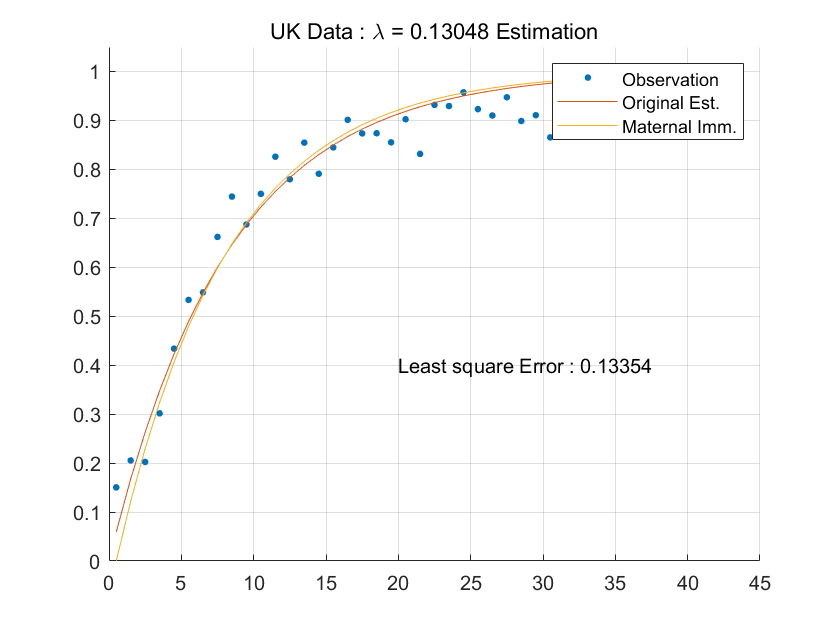

% best-fitting value for the force of infection
fun_uk_m = @(x) sum(2.*((1-exp(-x*(age_uk-0.5)))-p_sero_uk).*(exp(-x*(age_uk-0.5))).*(age_uk-0.5));
best_lam_uk_m = fzero(fun_uk_m,0.12);
est_uk_m= 1-exp(-best_lam_uk_m*(age_uk-0.5));
Error_uk_m = sum((est_uk_m-p_sero_uk).^2);

figure(4)
hold on
plot(age_uk,p_sero_uk,'.','MarkerSize',10)
plot(age_uk,est_uk,'-')
plot(age_uk,est_uk_m,'-')
legend('Observation','Original Est.','Maternal Imm.')
ylim([0,1.05])
title(['UK Data : \lambda = ',num2str(best_lam_uk_m),' Estimation'])
text(20,0.4,['Least square Error : ',num2str(Error_uk_m)])
grid on;
hold off

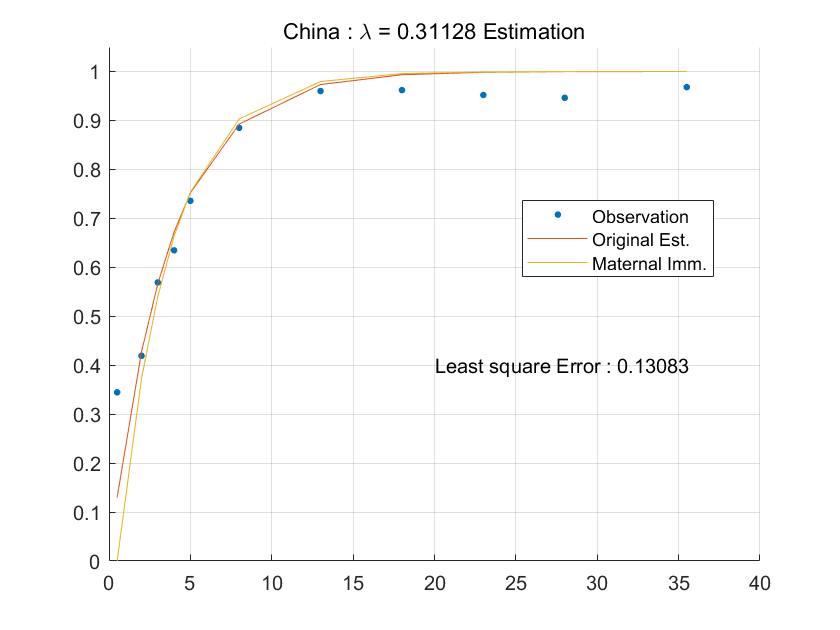

fun_ch_m = @(x) sum(2.*((1-exp(-x*(age_ch-0.5)))-p_sero_ch).*(exp(-x*(age_ch-0.5))).*(age_ch-0.5));
best_lam_ch_m = fzero(fun_ch_m,0.12);
est_ch_m= 1-exp(-best_lam_ch_m*(age_ch-0.5));
Error_ch_m = sum((est_ch_m-p_sero_ch).^2);

figure(5)
hold on
plot(age_ch,p_sero_ch,'.','MarkerSize',10)
plot(age_ch,est_ch,'-')
plot(age_ch,est_ch_m,'-')
legend('Observation','Original Est.','Maternal Imm.')
legend('Position',[0.62143,0.56226,0.22857,0.11905])
ylim([0,1.05])
title(['China : \lambda = ',num2str(best_lam_ch_m),' Estimation'])
text(20,0.4,['Least square Error : ',num2str(Error_ch_m)])
grid on;
hold off

#### **Time-dependency Force of Infection**

#### **Plot the graphs of –ln(Sa/Na) for China and the UK, where Sa is the number of susceptible at age “a” and Na is the number of population at age “a”.**

#### 10. According to the plots, is the assumption that the force of infection is independent of age in these populations justified? At what age does it look as though the force of infection changes in these populations?

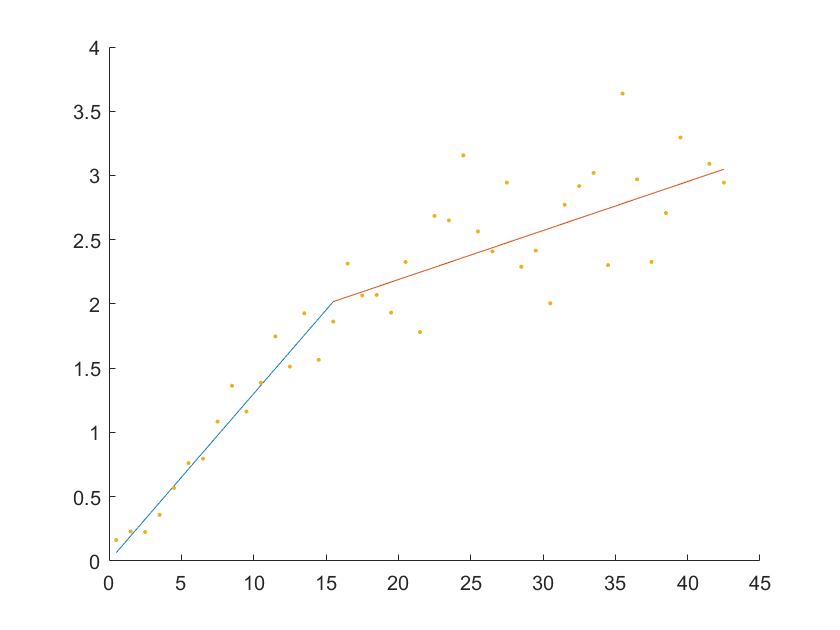

% data 가공
log_data_raw = -log(1-(p_sero_uk));
rm_p_sero = standardizeMissing(p_sero_uk,1);
Nan_index = isnan(rm_p_sero);
rm_data = rmmissing(rm_p_sero);
log_age = (1-Nan_index).*age_uk;
log_age = standardizeMissing(log_age,0);
log_age = rmmissing(log_age);
log_data = -log(1-rmmissing(rm_p_sero));
% data fitting
fun_1 = @(lam1) sum((1-exp(-lam1*log_age(1:16))-rm_data(1:16)).^2);
lambda_1 = fminsearch(fun_1,0.12);
fun_2 = @(lam2) sum((1-exp(-15.5.*(lambda_1-lam2)-lam2*log_age(16:end))-rm_data(16:end)).^2);
lambda_2 = fminsearch(fun_2,0.12);
figure(6)
hold on;
plot(log_age(1:16),lambda_1*log_age(1:16),'-');
plot(log_age(16:end),lambda_2*log_age(16:end)+15.5*(lambda_1-lambda_2),'-')
plot(log_age,log_data,'.');
hold off;

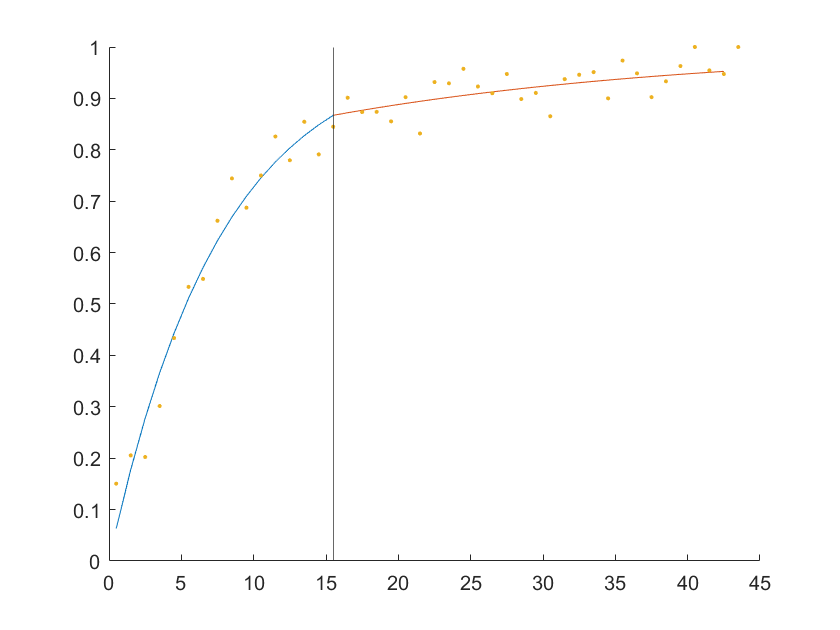

figure(7)
hold on;
plot(log_age(1:16),1-exp(-lambda_1*log_age(1:16)),'-');
plot(log_age(16:end),1-exp(-lambda_2*log_age(16:end)-15.5*(lambda_1-lambda_2)),'-')
plot(age_uk,p_sero_uk,'.');
xline(15.5)
hold off;

#### 11. Estimate the age-specific forces of infection using 2 age groups for the UK and China. Suggest reasons for the differences in the force of infection between China and the UK.

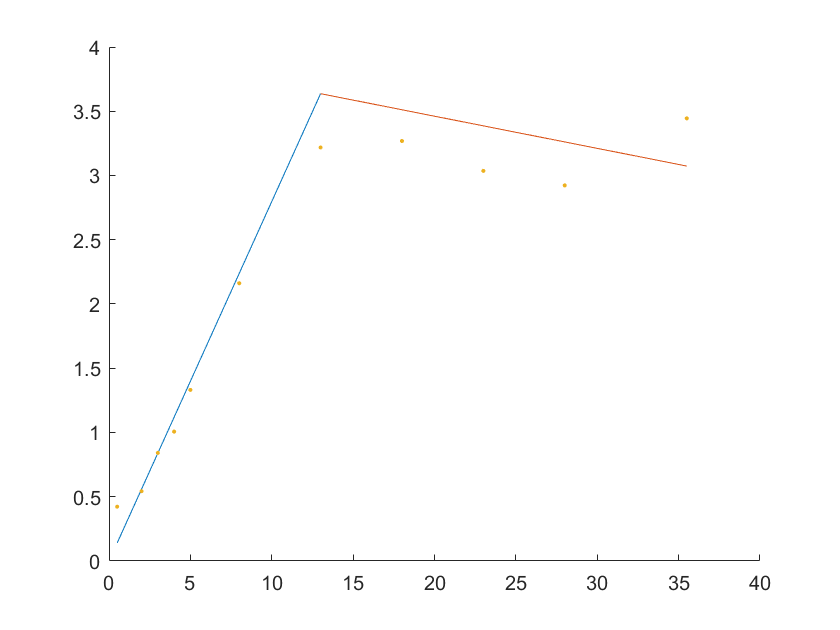

% data 가공
log_data_raw = -log(1-(p_sero_ch));
rm_p_sero = standardizeMissing(p_sero_ch,1);
Nan_index = isnan(rm_p_sero);
rm_data = rmmissing(rm_p_sero);
log_age = (1-Nan_index).*age_ch;
log_age = standardizeMissing(log_age,0);
log_age = rmmissing(log_age);
log_data = -log(1-rmmissing(rm_p_sero));

% data fitting
fun_1 = @(lam1) sum((1-exp(-lam1*log_age(1:7))-rm_data(1:7)).^2);
lambda_1 = fminsearch(fun_1,0.12);
fun_2 = @(lam2) sum((1-exp(-13.*(lambda_1-lam2)-lam2*log_age(7:end))-rm_data(7:end)).^2);
lambda_2 = fminsearch(fun_2,0.12);
figure(8)
hold on;
plot(log_age(1:7),lambda_1*log_age(1:7),'-');
plot(log_age(7:end),lambda_2*log_age(7:end)+13*(lambda_1-lambda_2),'-')
plot(log_age,log_data,'.');
hold off;

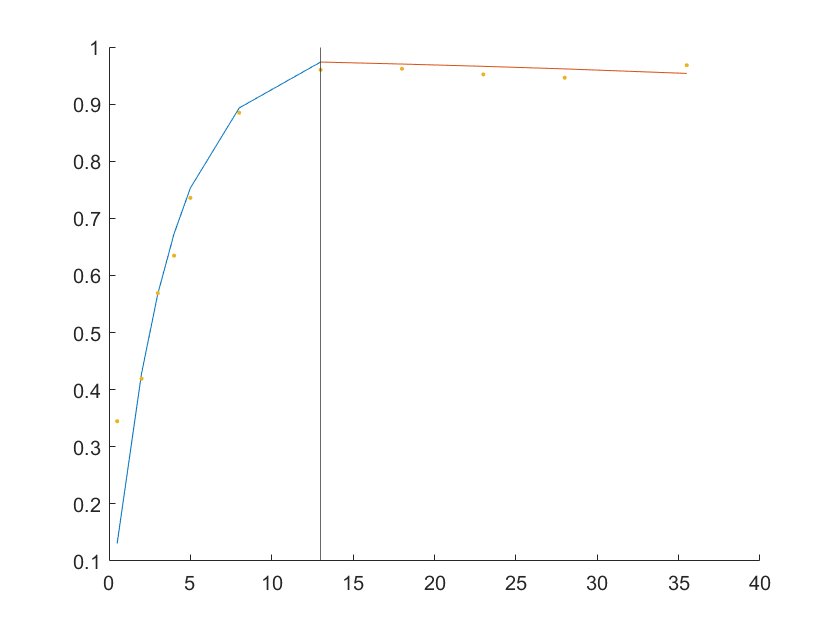

figure(9)
hold on;
plot(log_age(1:7),1-exp(-lambda_1*log_age(1:7)),'-');
plot(log_age(7:end),1-exp(-lambda_2*log_age(7:end)-13*(lambda_1-lambda_2)),'-')
plot(age_ch,p_sero_ch,'.');
xline(13)
hold off;